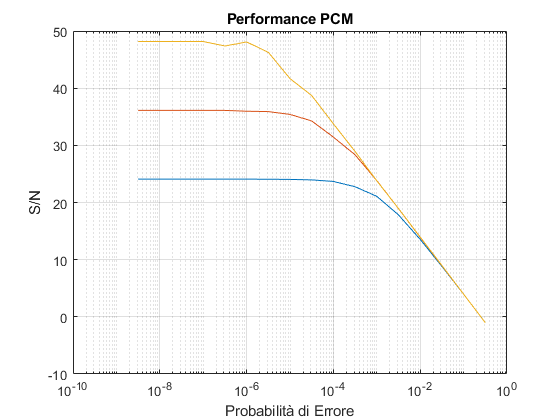

fc = 8e3;
Tc = 1/fc;
B = 1/(2*Tc);

Npti=1e6;

sig_in=2*rand(1,Npti)-1;

figure(1);

for nbit = 4:2:8
    M=2^nbit;
    V=1;
    DeltaV=2*V/M;
    pe = 1;
    
    partition=[-V+DeltaV:DeltaV:V-DeltaV];
    codebook=[-V+DeltaV/2:DeltaV:V-DeltaV/2];
    [index,quants]=quantiz(sig_in,partition,codebook);
    
    pe_arr = zeros(1, 18);
    sn_arr = zeros(1, 18);
    ind=1;
    for a = -9:0.5:-1
        pe = pe * sqrt(0.1);
        pe_arr(ind) = pe;
        
        word=de2bi(index,nbit);
        word_out=bsc(word,pe);

        index_out=bi2de(word_out);
        sig_out=codebook(index_out+1);
        err=sig_out-sig_in;
        
        N=var(err);
        S=var(sig_in);
        
        sn_arr(ind) = 10*log10(S/N);
        
        ind = ind+1;
    end
    semilogx(pe_arr, sn_arr)
    hold on
end

title('Performance PCM')
xlabel('Probabilità di Errore')
ylabel('S/N')
grid on